# Classify Large Multiresolution Images Using `blockedImage` and Deep Learning

This example shows how to classify multiresolution whole slide images (WSIs) that do not fit in memory using an Inception-v3 deep neural network.

The only definitive way to diagnose breast cancer is by examining tissue samples collected from biopsy or surgery. The samples are commonly prepared with hematoxylin and eosin (H&E) staining to increase the contrast of structures in the tissue. Traditionally, pathologists examine the tissue on glass slides under a microscope to detect tumor tissue. Diagnosis takes time as pathologists must thoroughly inspect an entire slide at close magnification. Further, pathologists may not notice small tumors. Deep learning methods aim to automate the detection of tumor tissue, saving time and improving the detection rate of small tumors.

Deep learning methods for tumor classification rely on digital pathology, in which whole tissue slides are imaged and digitized. The resulting WSIs have extremely high resolution. WSIs are frequently stored in a multiresolution file to facilitate the display, navigation, and processing of the images.

Reading WSIs is a challenge because the images cannot be loaded as a whole into memory and therefore require out-of-core image processing techniques. You can store and process this type of large multiresolution image by using [`blockedImage`](docid:images_ref#mw_284fc4ed-4502-4b5b-a71a-c6fcaf99ec77) objects. You can extract batches of data from `blockedImage` objects using [`blockedImageDatastore`](docid:images_ref#mw_5663dbb1-d615-442f-ba1e-28040fa1fe27) objects.

This example shows how to train a deep learning network to classify tumors in very large multiresolution images using `blockedImage` and `blockedImageDatastore`. The example presents classification results as heatmaps that depict the probability that local tissue is tumorous. The localization of tumor regions enables medical pathologists to investigate specific regions and quickly identify tumors of any size in an image.

## Download Training Data

This example uses WSIs from the Camelyon16 challenge [1]. The data from this challenge contains a total of 400 WSIs of lymph nodes from two independent sources, separated into 270 training images and 130 test images. The WSIs are stored as TIF files in a stripped format with an 11-level pyramid structure. 

The training data set consists of 159 WSIs of normal lymph nodes and 111 WSIs of lymph nodes with tumor and healthy tissue. Usually, the tumor tissue is a small fraction of the healthy tissue. Ground truth coordinates of the lesion boundaries accompany the tumor images.

The size of each training file is approximately 2 GB. If you do not want to download the training data set or train the network, then go directly to the Train or Download the Network section in this example.

Create a directory to store the training data set.

trainingImageDir = fullfile(tempdir,'Camelyon16','training');
if ~exist(trainingImageDir,'dir')
    mkdir(trainingImageDir);
    mkdir(fullfile(trainingImageDir,'normal'));
    mkdir(fullfile(trainingImageDir,'tumor'));
    mkdir(fullfile(trainingImageDir,'lesion_annotations'));
end

trainNormalDataDir = fullfile(trainingImageDir,'normal');
trainTumorDataDir = fullfile(trainingImageDir,'tumor');
trainTumorAnnotationDir = fullfile(trainingImageDir,'lesion_annotations');

To download the training data, go to the [Camelyon17](https://camelyon17.grand-challenge.org/Data/) website and click the first "CAMELYON16 data set" link. Open the "training" directory, then follow these steps.

- Download the "lesion_annotations.zip" file. Extract the files to the directory specified by the `trainTumorAnnotationDir` variable.

- Open the "normal" directory. Download the images to the directory specified by the `trainNormalDataDir` variable. 

- Open the "tumor" directory. Download the images to the directory specified by the `trainTumorDataDir` variable. 

Specify the number of training images. Note that one of the training images of normal tissue, 'normal_144.tif', has metadata that cannot be read by the `blockedImage` object. This example uses the remaining 158 training files.

numNormalFiles = 158;
numTumorFiles = 111;

## Visualize Training Data

To get a better understanding of the training data, display one training image. Because loading the entire image into memory at the finest resolution is not possible, you cannot use traditional image display functions such as `imshow`. To display and process the image data, use a [`blockedImage`](docid:images_ref#mw_284fc4ed-4502-4b5b-a71a-c6fcaf99ec77) object.

Create a `blockedImage` object from a tumor training image.

tumorFileName = fullfile(trainTumorDataDir,'tumor_001.tif');
tumorImage = blockedImage(tumorFileName);

Inspect the dimensions of the `blockedImage` at each resolution level. Level 1 has the most pixels and is the finest resolution level. Level 10 has the fewest pixels and is the coarsest resolution level. The aspect ratio is not consistent, which indicates that levels do not all span the same world area.

levelSizeInfo = table((1:length(tumorImage.Size))', ...
    tumorImage.Size(:,1), ...
    tumorImage.Size(:,2), ...
    tumorImage.Size(:,1)./tumorImage.Size(:,2), ...
    'VariableNames',["Resolution Level" "Image Width" "Image Height" "Aspect Ratio"])

Display the `blockedImage` at a coarse resolution level by using the [`bigimageshow`](docid:images_ref#object_bigimageshow) function. Return a handle to the `bigimageshow` object. You can use the handle to adjust the display. The image contains a lot of empty white space. The tissue occupies only a small portion of the image.

h = bigimageshow(tumorImage,'ResolutionLevel',8);

Zoom in on one part of the image by setting the horizontal and vertical spatial extents with respect to the finest resolution level. The image looks blurry because this resolution level is very coarse.

xlim([29471,29763]);
ylim([117450,118110]);

To see more details, change the resolution level to a finer level. 

h.ResolutionLevel = 1;

## Create Masks

You can reduce the amount of computation by processing only regions of interest (ROIs). Use a mask to define ROIs. A mask is a logical image in which `true` pixels represent the ROI.

To further reduce the amount of computation, create masks at a coarse resolution level that can be processed entirely in memory instead of on a block-by-block basis. If the spatial referencing of the coarse resolution level matches the spatial referencing of finer resolution levels, then locations at the coarse level correspond to locations in finer levels. In this case, you can use the coarse mask to select which blocks to process at the finer levels. For more information, see [Set Spatial Referencing for Big Images](docid:images_ug#mw_3ae2769f-a71d-4c0c-8ded-59c8b8381098) and [Process Big Images Efficiently Using Masks](docid:images_ug#mw_1c2b1c98-7014-4dd0-a55d-f3e309a9218e).

Specify a resolution level to use for creating the mask. This example uses resolution level 7, which is coarse and fits in memory. Note that the `blockedImage` object automatically sorts the levels in a multiresolution image from finest to coarsest based on number of pixels in each level. Several Camelyon16 image files contain a mask of intermediate resolution. This example ignores the mask when determining and reading the seventh level of image data.

resolutionLevel = 7;

### Create Masks for Normal Images

In normal images, the ROI consists of healthy tissue. The color of healthy tissue is distinct from the color of the background, so use color thresholding to segment the image and create an ROI. The L*a*b* color space provides the best color separation for segmentation. Convert the image to the L*a*b* color space, then threshold the a* channel to create the tissue mask.

You can use the helper function `createMaskForNormalTissue` to create masks using color thresholding. This helper function is attached to the example as a supporting file.

The helper function performs these operations on each training image of normal tissue:

- Create a `blockedImage` object from the TIF image file.

- Set the spatial referencing of all resolution levels from the image metadata.

- Get the image at the coarse resolution level.

- Convert the coarse image to the L*a*b* color space, then extract the a* channel.

- Create a binary image by thresholding the image using Otsu's method, which minimizes the intraclass variance between the black and white pixels.

- Create a single-resolution `blockedImage` object from the mask and set the spatial referencing of the mask to match the spatial referencing of the input image.

- Write the mask `blockedImage` to memory. Only the `blockedImage` object is in memory. The individual image blocks corresponding to the logical mask image are in a temporary directory. Writing to a directory preserves the custom spatial referencing, which ensures that the normal images and their corresponding mask images have the same spatial referencing.

trainNormalMaskDir = fullfile(trainNormalDataDir,['normal_mask_level' num2str(resolutionLevel)]);
createMaskForNormalTissue(trainNormalDataDir,trainNormalMaskDir,resolutionLevel)

Now that both normal images and masks are on disk, create `blockedImage` objects to manage the data by using the helper function `createBlockedImageAndMaskArrays`. This function creates an array of `blockedImage` objects from the normal images and a corresponding array of `blockedImage` objects from the normal mask images. The helper function is attached to the example as a supporting file.

[normalImages,normalMasks] = createBlockedImageAndMaskArrays(trainNormalDataDir,trainNormalMaskDir);

Select a sample normal image and mask. Confirm that the spatial world extents of the mask match the extents of the image at the finest resolution level. The spatial world extents are specified by the `WorldStart` and `WorldEnd` properties.

idx = 2;
[normalImages(idx).WorldStart normalImages(idx).WorldEnd]
[normalMasks(idx).WorldStart normalMasks(idx).WorldEnd]

Verify that the mask contains the correct ROIs and spatial referencing. Display the sample image by using the `bigimageshow` function. Get the axes containing the display. 

figure
hNormal = bigimageshow(normalImages(idx));
hNormalAxes = hNormal.Parent;

Create a new axes on top of the displayed `blockedImage`. In the new axes, display the corresponding mask image with partial transparency. The mask highlights the regions containing normal tissue.

hMaskAxes = axes;
hMask = bigimageshow(normalMasks(idx),'Parent',hMaskAxes, ...
    'Interpolation','nearest','AlphaData',0.5);
hMaskAxes.Visible = 'off';

Link the axes of the image with the axes of the mask. When you zoom and pan, both axes are updated identically.

linkaxes([hNormalAxes,hMaskAxes]);

Zoom in on one part of the image by setting the horizontal and vertical spatial extents. The mask overlaps the normal tissue correctly.

xlim([45000 80000]);
ylim([130000 165000]);

### Create Masks for Tumor Images

In tumor images, the ROI consists of tumor tissue. The color of tumor tissue is similar to the color of healthy tissue, so you cannot use color segmentation techniques. Instead, create ROIs by using the ground truth coordinates of the lesion boundaries that accompany the tumor images.

You can use the helper function `createMaskForTumorTissue` to create a mask using ROIs. This helper function is attached to the example as a supporting file.

The helper function performs these operations on each training image of tumor tissue:

- Create a `blockedImage` object from the TIF image file.

- Set the spatial referencing from the image metadata.

- Read the corresponding lesion annotations in XML files and convert the annotations to polygons ([`Polygon`](docid:images_ref#mw_59a12e0e-0780-4589-aac4-2a9ccb95336e) objects).

- For each image block, use the polygon data to create a mask for the corresponding block. Images with tumor regions can contain some normal regions within them. Use the annotations of normal tissue to exclude those regions.

- Create an output logical mask `blockedImage` object at a coarser resolution level. Write the mask image on a block-by-block basis by using the `setBlock` function.

- Write the mask `blockedImage` object to a directory in memory. Only the `blockedImage` object is in memory. The individual image blocks corresponding to the logical mask image are in a temporary directory. Writing to a directory preserves the custom spatial referencing, which ensures that the tumor images and their corresponding mask images have the same spatial referencing.

trainTumorMaskDir = fullfile(trainTumorDataDir,['tumor_mask_level' num2str(resolutionLevel)]);
createMaskForTumorTissue(trainTumorDataDir,trainTumorAnnotationDir, ...
    trainTumorMaskDir,resolutionLevel);

Now that both tumor images and masks are on disk, create `blockedImage` objects to manage the data by using the helper function `createBlockedImageAndMaskArrays`. This function creates an array of `blockedImage` objects from the tumor images and a corresponding array of `blockedImage` objects from the tumor mask images. The helper function is attached to the example as a supporting file.

[tumorImages,tumorMasks] = createBlockedImageAndMaskArrays(trainTumorDataDir,trainTumorMaskDir);

Select a sample tumor image and mask. Confirm that the spatial world extents of the mask match the extents of the image at the finest resolution level. The spatial world extents are specified by the `XWorldLimits` and `YWorldLimits` properties.

idx = 5;
[tumorImages(idx).WorldStart tumorImages(idx).WorldEnd]
[tumorMasks(idx).WorldStart tumorMasks(idx).WorldEnd]

Verify that the mask contains the correct ROIs and spatial referencing. Display the sample image by using the `bigimageshow` function. Get the axes containing the display. 

figure
hTumor = bigimageshow(tumorImages(idx));
hTumorAxes = hTumor.Parent;

Create a new axes on top of the displayed `blockedImage`. In the new axes, display the corresponding mask image with partial transparency. The mask highlights the regions containing normal tissue.

hMaskAxes = axes;
hMask = bigimageshow(tumorMasks(idx),'Parent',hMaskAxes, ...
    'Interpolation','nearest','AlphaData',0.5);
hMaskAxes.Visible = 'off';

Link the axes of the image with the axes of the mask. When you zoom and pan, both axes are updated identically.

linkaxes([hTumorAxes,hMaskAxes]);

Zoom in on one part of the image by setting the horizontal and vertical spatial extents. The mask overlaps the tumor tissue correctly.

xlim([45000 65000]);
ylim([130000 150000]);

## Create Blocked Image Datastores for Training and Validation

To extract patches of training data from the `blockedImage` objects, use a [`blockedImageDatastore`](docid:images_ref#mw_5663dbb1-d615-442f-ba1e-28040fa1fe27). This datastore reads patches of `blockedImage` data at a single resolution level.

Color imbalance and class imbalance in the raw training patches can potentially bias the network. Color imbalance results from nonuniform color staining of the tissue. Class imbalance results from an unequal amount of tumor and normal tissue in the data. To correct these imbalances, you can preprocess and augment the datastore.

This example shows how to create a `blockedImageDatastore` that extracts tumor and normal patches for training the network. The example also shows how to preprocess and augment datastores to avoid biasing the network.

### Select Location of Normal Tissue Patches to Read

Randomly split the normal images and corresponding masks into two sets. The validation set contains two randomly selected images and corresponding masks. The training set contains the remaining images and masks.

normalValnIdx = randi(numNormalFiles,[1 2]);
normalTrainIdx = setdiff(1:numNormalFiles,normalValnIdx);

The patch size is small compared to the size of features in the image. By default, a `blockedImageDatastore` extracts patches with no overlap and no gap, which generates a huge quantity of training patches. You can reduce the amount of training data by specifying a subset of patches. Specify the coordinates of patches using the [`selectBlockLocations`](docid:images_ref#mw_f4307216-5b45-415d-8d27-ff26f4ebe920) function. Add a gap between the sampled training patches using the `BlockOffsets` name-value argument. Specify an offset that is larger than the patch size. Increase the inclusion threshold from the default value of 0.5 so that the network trains on relatively homogenous patches.

patchSize = [299,299,3];
normalStrideFactor = 10;
blsNormalData = selectBlockLocations(normalImages(normalTrainIdx), ...
    "BlockSize",patchSize(1:2),"BlockOffsets",patchSize(1:2)*normalStrideFactor, ...
    "Masks",normalMasks(normalTrainIdx),"InclusionThreshold",0.75,"ExcludeIncompleteBlocks",true);

Select the location of validation patches to read. Because there are fewer validation images, you do not need to add a gap between patches.

blsNormalDataVal = selectBlockLocations(normalImages(normalValnIdx), ...
    "BlockSize",patchSize(1:2), ...
    "Masks",normalMasks(normalValnIdx),"InclusionThreshold",0.75,"ExcludeIncompleteBlocks",true);

### Create Datastores for Normal Images

Create datastores `dsNormalData` and `dsNormalDataVal` that read image patches from normal images at the finest resolution level for training and validation, respectively. Specify the coordinates of patches using the `BlockLocationSet` name-value pair argument.

dsNormalData = blockedImageDatastore(normalImages(normalTrainIdx), ...
    "BlockLocationSet",blsNormalData);
dsNormalDataVal = blockedImageDatastore(normalImages(normalValnIdx), ...
    "BlockLocationSet",blsNormalDataVal);

Preview patches from the datastore containing normal training images.

imagesToPreview = zeros([patchSize 10],'uint8');
for n = 1:10
    im = read(dsNormalData);
    imagesToPreview(:,:,:,n) = im{1};
end
figure
montage(imagesToPreview,'Size',[2 5],'BorderSize',10,'BackgroundColor','k');
title("Training Patches of Normal Tissue")

### Select Location of Tumor Tissue Patches to Read

Randomly split the tumor images and corresponding masks into two sets. The validation set contains two randomly selected images and corresponding masks. The training set contains the remaining images and masks.

tumorValIdx = randi(numTumorFiles,[1 2]);
tumorTrainIdx = setdiff(1:numTumorFiles,tumorValIdx);

Specify the coordinates of patches to read using the `selectBlockLocations` function. Tumor tissue is more sparse than normal tissue, so increase the sampling density by specifying a smaller block offset than for normal tissue. Note that if you want to train using fewer training images, then you might need to increase the size of the training set by decreasing the block offset even further.

tumorStrideFactor = 3;
blsTumorData = selectBlockLocations(tumorImages(tumorTrainIdx), ...
    "BlockSize",patchSize(1:2),"BlockOffsets",patchSize(1:2)*tumorStrideFactor, ...
    "Masks",tumorMasks(tumorTrainIdx),"InclusionThreshold",0.75,"ExcludeIncompleteBlocks",true);

Select the location of validation patches to read. Because there are fewer validation images, you do not need to add a gap between patches.

blsTumorDataVal = selectBlockLocations(tumorImages(tumorValIdx), ...
    "BlockSize",patchSize(1:2), ...
    "Masks",tumorMasks(tumorValIdx),"InclusionThreshold",0.75,"ExcludeIncompleteBlocks",true);

### Create Datastores for Tumor Images

Create a `blockedImageDatastore` from the training tumor images and masks. The datastores `dsTumorData` and `dsTumorDataVal` read image patches from tumor images at the finest resolution level for training and validation, respectively.

dsTumorData = blockedImageDatastore(tumorImages(tumorTrainIdx), ...
    "BlockLocationSet",blsTumorData);
dsTumorDataVal = blockedImageDatastore(tumorImages(tumorValIdx), ...
    "BlockLocationSet",blsTumorDataVal);

Preview patches from the datastore containing tumor training images.

imagesToPreview = zeros([patchSize 10],'uint8');
for n = 1:10
    im = read(dsTumorData);
    imagesToPreview(:,:,:,n) = im{1};
end
montage(imagesToPreview,'Size',[2 5],'BorderSize',10,'BackgroundColor','k');
title("Training Patches of Tumor Tissue")

### Normalize Colors and Augment Training Data

The training images have different color distributions because the data set came from different sources and color staining the tissue does not result in identically stained images. Additional preprocessing is necessary to avoid biasing the network.

To prevent color variability, this example preprocesses the data with standard stain normalization techniques. Apply stain normalization and augmentation by using the [`transform`](docid:matlab_ref#mw_16489124-fe7e-4381-b715-8d3b8b30a9f6) function with custom preprocessing operations specified by the helper function `augmentAndLabelCamelyon16`. This function is attached to the example as a supporting file.

The `augmentAndLabelCamelyon16` function performs these operations:

- Normalize staining by using the [`normalizeStaining.m`](matlab:edit(fullfile(matlabroot,'examples','deeplearning_shared','main','normalizeStaining.m'))) function [4]. Stain normalization is performed using Macenko's method, which separates H&E color channels by color deconvolution using a fixed matrix and then recreates the normalized images with individual corrected mixing. The function returns the normalized image as well as the H&E images.

- Add color jitter by using the [`jitterColorHSV`](docid:images_ref#mw_3c1f1fef-ccb7-45d6-88f6-3e61011a69df) function. Color jitter varies the color of each patch by perturbing the image contrast, hue, saturation, and brightness. Color jitter is performed in the HSV color space to avoid unwanted color artifacts in the RGB image.

- Apply random combinations of 90 degree rotations and vertical and horizontal reflection. Randomized affine transformations make the network agnostic to the orientation of the input image data.

- Label the patch as `'normal'` or `'tumor'`. 

Each image patch generates five augmented and labeled patches: the stain-normalized patch, the stain-normalized patch with color jitter, the stain-normalized patch with color jitter and random affine transformation, the hematoxylin image with random affine transformation, and the eosin image with random affine transformation.

Create datastores that transform the normal training and validation images and label the generated patches as `'normal'`.

dsLabeledNormalData = transform(dsNormalData, ...
    @(x,info)augmentAndLabelCamelyon16(x,info,'normal'),'IncludeInfo',true);
dsLabeledNormalDataVal = transform(dsNormalDataVal, ...
    @(x,info)augmentAndLabelCamelyon16(x,info,'normal'),'IncludeInfo',true);

Create datastores that transform the tumor training and validation images and label the generated patches as `'tumor'`.

dsLabeledTumorData = transform(dsTumorData, ...
    @(x,info)augmentAndLabelCamelyon16(x,info,'tumor'),'IncludeInfo',true);
dsLabeledTumorDataVal = transform(dsTumorDataVal, ...
    @(x,info)augmentAndLabelCamelyon16(x,info,'tumor'),'IncludeInfo',true);

### Balance Tumor and Normal Classes

The amount of cancer tissue in the tumor images is very small compared to the amount of normal tissue. Additional preprocessing is necessary to avoid training the network on class-imbalanced data containing a large amount of normal tissue and a very small amount of tumor tissue.

To prevent class imbalance, this example defines a custom datastore called a `randomSamplingDatastore` that randomly selects normal and tumor training patches in a balanced way. The script to define this custom datastore is attached to the example as a supporting file. For more information, see [Develop Custom Datastore](docid:import_export#mw_697a5fc6-1077-4d16-a6f2-e84af20951c7).

Create the custom `randomSamplingDatastore` from the normal and tumor training datastores. The random sampling datastore `dsTrain` provides mini-batches of training data to the network at each iteration of the epoch.

dsTrain = randomSamplingDatastore(dsLabeledTumorData,dsLabeledNormalData);

To limit the number of patches used during validation, this example defines a custom datastore called a `validationDatastore` that returns five validation patches from each class. The script to define this custom datastore is attached to the example as a supporting file.

Create the custom `validationDatastore` from the normal and tumor validation datastores.

numValidationPatchesPerClass = 5;
dsVal = validationDatastore(dsLabeledTumorDataVal, ...
    dsLabeledNormalDataVal,numValidationPatchesPerClass);

## Set Up Inception-v3 Network Layers

This example uses the Inception-v3 network, a convolutional neural network that is trained on more than a million images from the ImageNet database [3]. The network is 48 layers deep and can classify images into 1,000 object categories, such as keyboard, mouse, pencil, and many animals. The network expects an image input size of 299-by-299 with 3 channels.

The [`inceptionv3`](docid:nnet_ref#mw_3bb6ba60-19b1-4bb0-b6d1-2810b754e2e4) function returns a pretrained Inception-v3 network. Inception-v3 requires the Deep Learning Toolbox™ Model for Inception-v3 Network support package. If this support package is not installed, then the function provides a download link.

net = inceptionv3;

### Replace Final Layers

The convolutional layers of the network extract image features that the last learnable layer and the final classification layer use to classify the input image. These two layers contain information on how to combine the features that the network extracts into class probabilities, a loss value, and predicted labels. To retrain a pretrained network to classify new images, replace these two layers with new layers adapted to the new data set. For more information, see [Train Deep Learning Network to Classify New Images](docid:nnet_ug#mw_50469739-1a06-4865-b1b2-e9c149b86f96).

Extract the layer graph from the trained network.

lgraph = layerGraph(net);

Find the names of the two layers to replace by using the supporting function `findLayersToReplace`. This function is attached to the example as a supporting file. In Inception-v3, these two layers are named `'predictions'` and `'ClassificationLayer_predictions'`.

[learnableLayer,classLayer] = findLayersToReplace(lgraph)

The goal of this example is to perform binary segmentation between two classes, tumor and nontumor regions. Create a new fully connected layer for two classes. Replace the original final fully connected layer with the new layer.

numClasses = 2;
newLearnableLayer = fullyConnectedLayer(numClasses,'Name','predictions');
lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

Create a new classification layer for two classes. Replace the original final classification layer with the new layer.

newClassLayer = classificationLayer('Name','ClassificationLayer_predictions');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

## Specify Training Options

Train the network using the `rmsprop` optimization solver. This solver automatically adjusts the learning rate and momentum for faster convergence. Specify other hyperparameter settings by using the [`trainingOptions`](docid:nnet_ref#bu59f0q) function. Reduce `MaxEpochs` to a small number because the large amount of training data enables the network to reach convergence sooner.

checkpointsDir = fullfile(trainingImageDir,'checkpoints');
if ~exist(checkpointsDir,'dir')
    mkdir(checkpointsDir);
end

options = trainingOptions('rmsprop', ...
    'InitialLearnRate',1e-5, ...
    'SquaredGradientDecayFactor',0.99, ...
    'MaxEpochs',3, ...
    'MiniBatchSize',32, ...
    'Plots','training-progress', ...
    'CheckpointPath',checkpointsDir, ...
    'ValidationData',dsVal, ...
    'ExecutionEnvironment','auto', ...
    'Shuffle','every-epoch');

## Train or Download the Network

By default, the example downloads a pretrained version of the trained Inception-v3 network by using the helper function `downloadTrainedCamelyonNet`. The helper function is attached to the example as a supporting file. The pretrained network enables you to run the entire example without waiting for training to complete.

To train the network, set the `doTraining` variable in the following code to `true`. Train the network using the [`trainNetwork`](docid:nnet_ref#bu6sn4c) function.

Train on a GPU if one is available. Using a GPU requires Parallel Computing Toolbox™ and a CUDA® enabled NVIDIA® GPU. For more information, see [GPU Support by Release](docid:distcomp_ug#mw_57e04559-0b60-42d5-ad55-e77ec5f5865f). Training takes about 20 hours on an NVIDIA Titan X.

doTraining = false;
if doTraining
    trainedNet = trainNetwork(dsTrain,lgraph,options);
    modelDateTime = string(datetime('now','Format',"yyyy-MM-dd-HH-mm-ss"));
    save(strcat("trainedCamelyonNet-",modelDateTime,".mat"),'trainedNet');
else
    trainedCamelyonNet_url = 'https://www.mathworks.com/supportfiles/vision/data/trainedCamelyonNet.mat';
    netDir = fullfile(tempdir,'Camelyon16');
    downloadTrainedCamelyonNet(trainedCamelyonNet_url,netDir);
    load(fullfile(netDir,'trainedCamelyonNet.mat'));
end

## Download and Preprocess Test Data

The Camelyon16 test data set consists of 130 WSIs. These images have both normal and tumor tissue. This example uses two test images from the Camelyon16 test data. The size of each file is approximately 2 GB.

Create a directory to store the test data.

testingImageDir = fullfile(tempdir,'Camelyon16','testing');
if ~exist(testingImageDir,'dir')
    mkdir(testingImageDir);
    mkdir(fullfile(testingImageDir,'images'));
    mkdir(fullfile(testingImageDir,'lesion_annotations'));
end

testDataDir = fullfile(testingImageDir,'images');
testTumorAnnotationDir = fullfile(testingImageDir,'lesion_annotations');

To download the test data, go to the [Camelyon17](https://camelyon17.grand-challenge.org/Data/) website and click the first "CAMELYON16 data set" link. Open the "testing" directory, then follow these steps.

- Download the "lesion_annotations.zip" file. Extract all files to the directory specified by the `testTumorAnnotationDir` variable.

- Open the "images" directory. Download the first two files, "test_001.tif" and "test_002.tif". Move the files to the directory specified by the `testDataDir` variable.

Specify the number of test images.

numTestFiles = 2;

### Create Masks for Test Images 

The test images contain a mix of normal and tumor images. To reduce the amount of computation during classification, define the ROIs by creating masks.

Specify a resolution level to use for creating the mask. This example uses resolution level 7, which is coarse and fits in memory.

resolutionLevel = 7;

Create masks for regions containing tissue. You can use the helper function `createMaskForNormalTissue` to create masks using color thresholding. This helper function is attached to the example as a supporting file. For more information about this helper function, see Create Masks for Normal Images.

testTissueMaskDir = fullfile(testDataDir,['test_tissuemask_level' num2str(resolutionLevel)]);
createMaskForNormalTissue(testDataDir,testTissueMaskDir,resolutionLevel);

Create masks for images that contain tumor tissue. Skip images that do not contain tumor tissue. You can use the helper function `createMaskForTumorTissue` to create masks using ROI objects. This helper function is attached to the example as a supporting file. For more information about this helper function, see Create Masks for Tumor Images.

testTumorMaskDir = fullfile(testDataDir,['test_tumormask_level' num2str(resolutionLevel)]);
createMaskForTumorTissue(testDataDir,testTumorAnnotationDir,testTumorMaskDir,resolutionLevel);

## Classify Test Data and Create Heatmaps

Each test image has two masks, one indicating normal tissue and one indicating tumor tissue. Create `blockedImage` objects to manage the test data and masks by using the helper function `createBlockedImageAndMaskArrays`. The helper function is attached to the example as a supporting file.

[testImages,testTissueMasks] = createBlockedImageAndMaskArrays(testDataDir,testTissueMaskDir);
[~,testTumorMasks] = createBlockedImageAndMaskArrays(testDataDir,testTumorMaskDir);

Use the trained Inception-v3 network to identify tumor patches in the test images, `testImages`. Classify the test images on a block-by-block basis by using the [`apply`](docid:images_ref#mw_d2a929bc-2fd0-45b6-b4ed-0e2671850b23) function with a custom processing pipeline specified by the helper function `tumorProbabilityHeatMap`. This helper function is attached to the example as a supporting file. To reduce the amount of computation required, specify the tissue mask `testTissueMask` so that the `apply` function processes only patches that contain tissue. Specify the `'UseParallel'` name-value pair argument as as the boolean returned by [`canUseGPU`](docid:matlab_ref#mw_9c1137a1-79ed-4efb-8234-814840e5e5a4). If a supported GPU is available for computation, then `apply` function evaluates blocks in parallel.

The `tumorProbabilityHeatMap` function performs these operations on each tissue block:

- Calculate the tumor probability score by using the [`predict`](docid:nnet_ref#function_dlnetwork.predict) function.

- Create a heatmap image patch with pixel values equal to the tumor probability score.

The `apply` function stitches the heatmap of each block into a single heatmap for the test image. The heatmap shows where the network detects regions containing tumors.

To visualize the heatmap, overlay the heatmap on the original image and set the transparency `'AlphaData'` property as the tissue mask. The overlay shows how well the tumor is localized in the image. Regions with a high probability of being tumors are displayed with red pixels. Regions with a low probability of being tumors are displayed as blue pixels. 

outputHeatmapsDir = fullfile(testingImageDir,'heatmaps');
if ~exist(outputHeatmapsDir,'dir')
    mkdir(outputHeatmapsDir);
end

patchSize = [299,299,3];

for idx = 1:numTestFiles
    bls = selectBlockLocations(testImages(idx),'BlockSize',patchSize(1:2),'Mask',testTissueMasks(idx),...
        'InclusionThreshold',0,'Levels',1);
    testHeatMaps(idx) = apply(testImages(idx),@(x)tumorProbabilityHeatMap(x,trainedNet), ...
        'Level',1,'BlockLocationSet',bls,'UseParallel',canUseGPU,'OutputLocation',outputHeatmapsDir);

    figure
    hTest = bigimageshow(testImages(idx));
    hTestAxes = hTest.Parent;
    hTestAxes.Visible = 'off';

    hMaskAxes = axes;
    hMask = bigimageshow(testHeatMaps(idx),'Parent',hMaskAxes, ...
        "Interpolation","nearest","AlphaData",testTissueMasks(idx));
    colormap(jet(255));
    hMaskAxes.Visible = 'off';

    linkaxes([hTestAxes,hMaskAxes]);
    title(['Tumor Heatmap of Test Image ',num2str(idx)]);
end

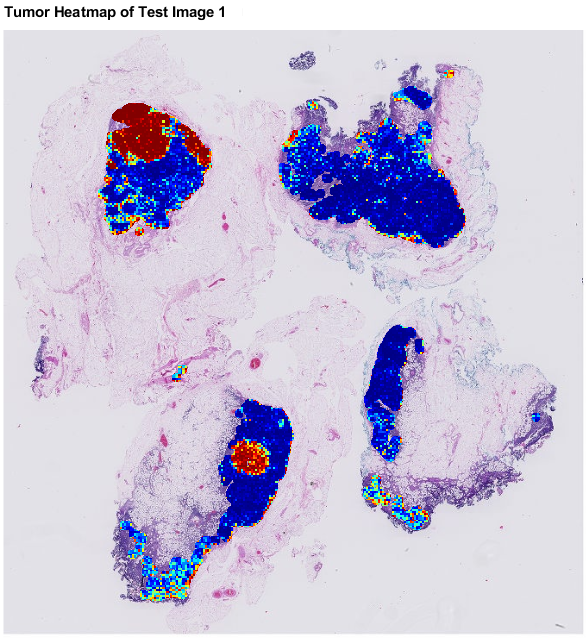

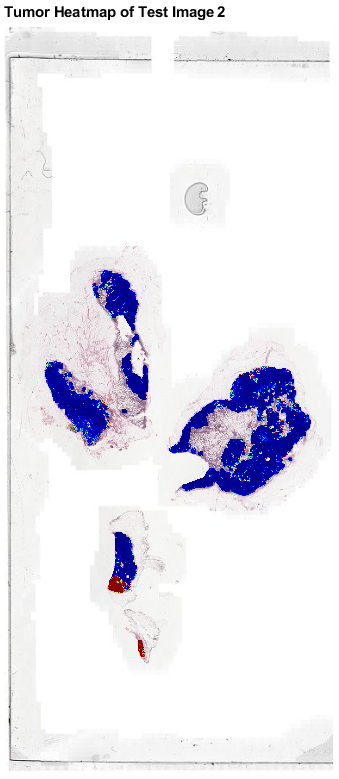

## References

[1] Ehteshami B. B., et al. "Diagnostic Assessment of Deep Learning Algorithms for Detection of Lymph Node Metastases in Women With Breast Cancer." *Journal of the American Medical Association*. Vol. 318, No. 22, 2017, pp. 2199–2210. [doi:10.1001/jama.2017.14585](https://jamanetwork.com/journals/jama/article-abstract/2665774)

[2] Szegedy, C., V. Vanhoucke, S. Ioffe, J. Shlens, and Z. Wojna. "Rethinking the Inception Architecture for Computer Vision." In *Proceedings of the IEEE Conference on Computer Vision and Pattern Recognition*, 2818–2826. Las Vegas, NV: IEEE, 2016.

[3] ImageNet. http://www.image-net.org.

[4] Macenko, M., et al. "A Method for Normalizing Histology Slides for Quantitative Analysis." In *2009 IEEE International Symposium on Biomedical Imaging: From Nano to Macro*, 1107–1110. Boston, MA: IEEE, 2009.

[5] xml2struct [https://www.mathworks.com/matlabcentral/fileexchange/28518-xml2struct](https://www.mathworks.com/matlabcentral/fileexchange/28518-xml2struct).

*Copyright 2020 The MathWorks, Inc.*